# Robotics 1 - September 11, 2019

## Exercise 1

% syms t
% sigma = [0,0,0]
% syms d1 real
% syms a2 real
% syms a3 real
% syms t real
% n = length(sigma)
% q = sym('q',[n,1],'real')
% d1_=5;
% a2_=3%4;
% a3_=3;
% % L = sym('L',[n,1])
% dhTable = [ pi/2,0, d1, q(1);
%             0,a2, 0, q(2);
%             0,a3, 0, q(3);
%             ]

% [T_Total T_Partial,R_Total,R_Partial,P_Total, P_Partial] = getTransformationMatrix(dhTable, 'alpha')
% 

% sincos =getShortNotation_SinCos(n);
% toShortNotation(T_Total,sincos)

% % A_e_p = [1,0,0,0.2;
% %          0,1,0,0.3;
% %          0,0,1,0;
% %          0,0,0,1];
% % 
% % Te = A_e_p*T_Total
% % toShortNotation(Te,sincos)

% sigma;
% [Jp, Jo] = getJacobian(dhTable, sigma, 'alpha');
% toShortNotation(Jp,sincos)

% det_jP=simplify(det(Jp))
% [JacobianSinFac,JacobianSinFac_s] =JacobianSingularities(Jp,3)
% 

## singularitis when

% singdet=prod(JacobianSinFac)
% solve(det_jP==0)%singularity not found, wrong?
% % another way to find solutions
% soldet1=solve(singdet==0,q)%singularity not found, wrong?
% q_singular=solvetoarray(soldet1,q)
% 
% q_ = [pi/2; pi/4; pi/2];
% qd_=[1;2;-2];
% qdd_=[0;0;0]

% % L_ = [1;0.5;0.25]
% digits(5)
% P_Total_=vpa(subs(P_Total, [q;d1;a2;a3], [q_;d1_;a2_;a3_]))
% Jp_ = vpa(subs(Jp, [q;d1;a2;a3], [q_;d1_;a2_;a3_]))
% det(Jp_)
% pseudoJp_=pinv(Jp_)
% % v=jacobian(P_Total,q)
% % acc=jacobian(v,q)
% % Tao_g=-Jp_*
% % eval(Jp_)*[0;-9.8*7;0]

% var_ind = 't';
% var_dep = 'q';
% var_set =[]
% syms(var_ind)
% for i=1:n
%    var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
% %    syms(var_dep_str);
%    var_set = [var_set str2sym(var_dep_str)]; % appends the variable to the set
% end
% assume(var_set,'real');
% q_d1=sym('q%d_d1',[n,1],'real');
% qd=sym('qd',[n,1],'real');
% 
% qdd=sym('qdd',[n,1],'real');
% 
% qt = var_set';
% qdt = diff(qt,t);
% qddt = diff(qdt,t);

% % 
% % % back to normal coordinates.
% P_Total=subs(P_Total,[d1,a2,a3],[d1_,a2_,a3_]);
% Jp1=subs(Jp,[d1,a2,a3],[d1_,a2_,a3_]);
% 
% P_Total_t = subs(P_Total,q,qt)
% vel=diff(P_Total_t,t);
% acc=diff(vel,t);
% accn=subs(acc,diff(diff(qt)),qdd);
% accn=subs(accn,diff(qt),qd);
% accn=subs(accn,qt,q);
% acc_0=subs(accn,[q,qd],[q_,qd_])
% acc_0_=[0;0;0]
% qdd_=solve(acc_0==acc_0_)
% Jp_t=subs(Jp1,[q],qt)
% %,[d1,a2,a3],[d1_,a2_,a3_])

% % 
% Jp_dt=diff(Jp_t,t)
% Jp_d=shortdiff(Jp_dt,sym2cell(qt),t,true,1)
% Jp_d_=vpa(subs(Jp_d,[q,q_d1],[q_,qd_]))
% 
% q_d2_=-pseudoJp_*Jp_d_*qd_


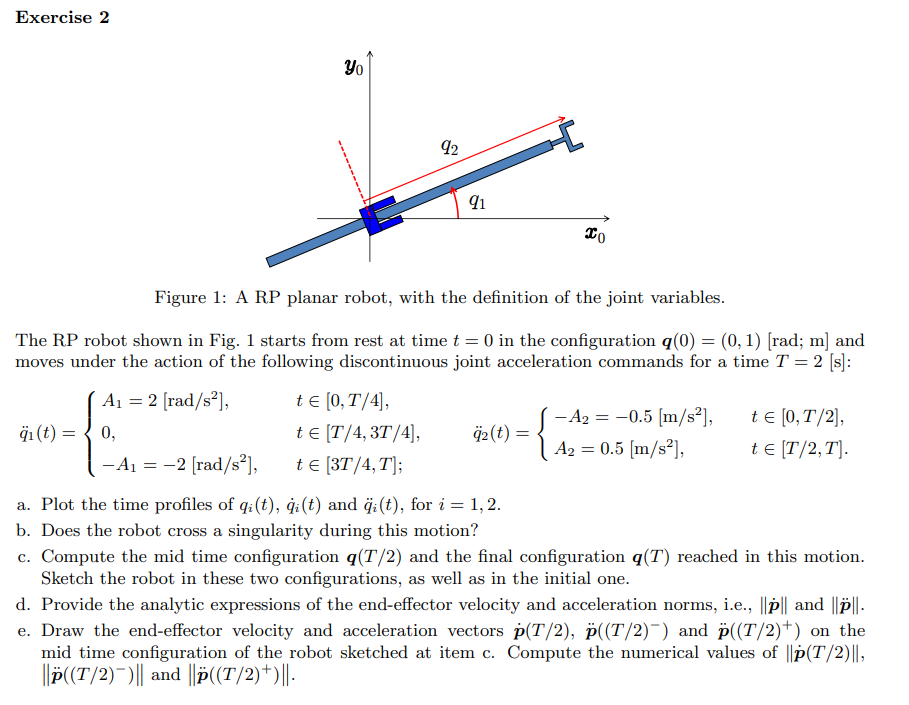

## case a

clear all;
close all;
clc;
T=sym('T','real');
V1=sym('V1','real');
A1=sym('A1','real');
A1_=2;
T_=2;
Ts=T/4;
V1=Ts*A1;
V1_=1;
qA=[0,1]'

qA =      0
     1


qB=sym('qB',[2,1],'real');

[qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)

$$qa\_piece1 = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ 0 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ A_{1}\,\mathrm{Ts} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ A_{1}\,\mathrm{Ts}-A_{1}\,\left(\mathrm{Ts}-T+t\right) & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ -\frac{A_{1}\,\mathrm{Ts}\,\left(\mathrm{Ts}-2\,t\right)}{2} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,\mathrm{Ts}-2\,T\,t+2\,{\mathrm{Ts}}^{2}+t^{2}\right)}{2} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ 0 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ A_{1}\,\left(T-t\right) & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ \frac{V_{1}\,\left(2\,t-\frac{V_{1}}{A_{1}}\right)}{2} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,t+\frac{2\,{V_{1}}^{2}}{{A_{1}}^{2}}+t^{2}-\frac{2\,T\,V_{1}}{A_{1}}\right)}{2} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{V_{1}+A_{1}\,t}{A_{1}} \end{array}$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 2.0 & \text{ if }t\in \left[0.0,0.5\right)\\ 0.0 & \text{ if }t\in \left[0.5,1.5\right)\\ -2.0 & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 2.0\,t & \text{ if }t\in \left[0.0,0.5\right)\\ 1.0 & \text{ if }t\in \left[0.5,1.5\right)\\ 4.0-2.0\,t & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right.\\ \left\{ \begin{array}{cl} t^{2} & \text{ if }t\in \left[0.0,0.5\right)\\ t-0.25 & \text{ if }t\in \left[0.5,1.5\right)\\ -1.0\,t^{2}+4.0\,t-2.5 & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right. \end{array}\right)$$

T_ = 2

Ts_ = 0.5000

% fplot(qa_piece2(1,:),[0,T_])
% figure
% fplot(qa_piece2(2,:),[0,T_])
% figure
% fplot(qa_piece2(3,:),[0,T_])


## case b


T=sym('T','real');
V2=sym('V2','real');
A2=sym('A2','real');
A2_=-0.5;
T_=2;
% Ts=T/4;
% V1_=1;
% qA=[0,1]'
qB=sym('qB',[2,1],'real');

[qa_piece3,T2_,V2_] = BangBangPRofile(qA(2,1),qB(2,1), A2_,T_)

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2}+1 & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2}+1 & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

$$qa\_piece3 = \left(\begin{array}{c} \left\{ \begin{array}{cl} -0.5 & \text{ if }t\in \left[0.0,1.0\right)\\ 0.5 & \text{ if }t\in \left[1.0,2.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} -0.5\,t & \text{ if }t\in \left[0.0,1.0\right)\\ 0.5\,t-1.0 & \text{ if }t\in \left[1.0,2.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 1.0-0.25\,t^{2} & \text{ if }t\in \left[0.0,1.0\right)\\ 0.25\,{\left(t-1.0\right)}^{2}-0.5\,t+1.25 & \text{ if }t\in \left[1.0,2.0\right) \end{array}\right. \end{array}\right)$$

T2_ = 2

V2_ = -0.5000

% fplot(qa_piece3(1,:),[0,T_])
% figure
% fplot(qa_piece3(2,:),[0,T_])
% figure
% fplot(qa_piece3(3,:),[0,T_])


## DHTAble

q = sym('q',[2,1],'real')

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

qd = sym('qd',[2,1],'real')

$$qd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2} \end{array}\right)$$

qdd = sym('qdd',[2,1],'real')

$$qdd = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\\ {\mathrm{qdd}}_{2} \end{array}\right)$$


links = [
    Revolute('alpha', pi/2, 'a', 0,'d', 0,'offset',pi/2);
    Prismatic('qlim', [0 5],'alpha',0,'theta',0);

    ];
% c600 = SerialLink(links);
% c600.teach([0 50],'view','top')
dhTable = [ pi/2,0, 0, q(1)+pi/2;
            0,0, q(2),0;
            ]

$$dhTable = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 0 & q_{1}+\frac{\pi }{2}\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

[T_Total T_Partial,R_Total,R_Partial,P_Total, P_Partial] = getTransformationMatrix(dhTable, 'alpha');
sigma=['RP']

sigma = 'RP'

[Jp, Jo] = getJacobian(dhTable, sigma, 'alpha')

$$Jp = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$Jo = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$


[V,W,A,Aw]=generalkinematics([Jp; Jo],P_Total,1,q);
simplify(V)

$$ans = \left(\begin{array}{c} {\mathrm{qd}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{qd}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

simplify(A)

$$ans = \left(\begin{array}{c} -q_{2}\,\cos\left(q_{1}\right)\,{{\mathrm{qd}}_{1}}^{2}-2\,{\mathrm{qd}}_{2}\,\sin\left(q_{1}\right)\,{\mathrm{qd}}_{1}+{\mathrm{qdd}}_{2}\,\cos\left(q_{1}\right)-q_{2}\,{\mathrm{qdd}}_{1}\,\sin\left(q_{1}\right)\\ -q_{2}\,\sin\left(q_{1}\right)\,{{\mathrm{qd}}_{1}}^{2}+2\,{\mathrm{qd}}_{2}\,\cos\left(q_{1}\right)\,{\mathrm{qd}}_{1}+{\mathrm{qdd}}_{2}\,\sin\left(q_{1}\right)+q_{2}\,{\mathrm{qdd}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

% luca aproach % da lo mismo
% Rtest=[cos(q(1)),-sin(q(1));sin(q(1)),cos(q(1))]
% phj=[qd(2);q(2)*qd(1)]
% phj2=[qdd(2)-q(2)*(qd(1)^2);q(2)*qdd(1)+2*qd(1)*qd(2)]
% Aluca=expand(Rtest*phj2) 

norm_A=horner(simplify(norm(A)))

$$norm\_A = \sqrt{{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{4}+{q_{2}}^{2}\,{{\mathrm{qdd}}_{1}}^{2}-2\,q_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\mathrm{qdd}}_{2}+4\,q_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,{\mathrm{qdd}}_{1}+4\,{{\mathrm{qd}}_{1}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+{{\mathrm{qdd}}_{2}}^{2}}$$

norm_V=horner(simplify(norm(V)))

$$norm\_V = \sqrt{{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{2}+{{\mathrm{qd}}_{2}}^{2}}$$


%lo demas se termina en papel

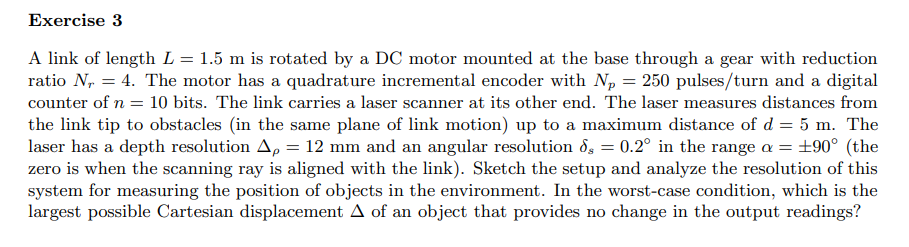

torad=pi/180;
Np=250%pulses/turn for a incremental encoder in cuadrature
Nr=4%ratio reduction
alpham=360/(4*Np)*torad
deltap=12/1000;
angularres=0.2*torad;
measureble=
